# Mobile Robot

format compact
close all
clear
clc

## Car-like mobile robots

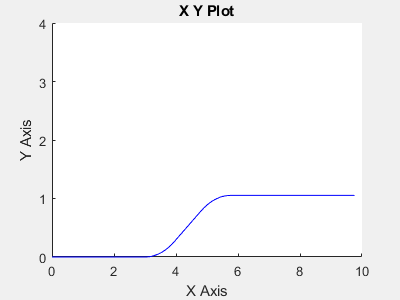

out =   Simulink.SimulationOutput:

                      t: [504x1 double] 
                      y: [504x4 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


sl_lanechange

% we can't push the simulate button on the Simulink model from this script so we simulate it
out = sim('sl_lanechange')  


out

out =   Simulink.SimulationOutput:

                      t: [504x1 double] 
                      y: [504x4 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


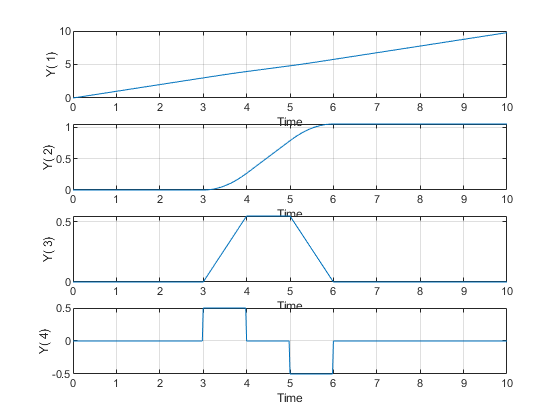

Error using matlab.graphics.shape.internal.AnnotationPane/set
Unrecognized property UIContextMenu for class AnnotationPane.
Error in mplot>mtools (line 238)
        set(c, 'UIContextMenu', h);
Error in mplot (


t = out.get('t'); q = out.get('y');

figure
mplot(t, q)

clf
plot(q(:,1), q(:,2))

## Moving to a point

bdclose('all');

sl_drivepoint

xg = [5 5];

x0 = [8 5 pi/2];

r = sim('sl_drivepoint');

q = r.find('y');

plot(q(:,1), q(:,2));

## Following a line

bdclose('all');

sl_driveline

L = [1 -2 4];

x0 = [8 5 pi/2];

r = sim('sl_driveline');

## Following a trajectory

bdclose('all');

sl_pursuit

r = sim('sl_pursuit')

## Moving to a pose

bdclose('all');

sl_drivepose

xg = [5 5 pi/2];

x0 = [9 5 0];

r = sim('sl_drivepose');

q = r.find('y');
clf
plot(q(:,1), q(:,2));

## Flying robots

bdclose('all');

sl_quadrotor

mdl_quadrotor

sim('sl_quadrotor');


about result

plot(result(:,1), result(:,2:3));


bdclose('all')